# Practice Thresholding Grayscale Images

## Introduction

Previously you learned about segmenting grayscale images using:

- global binarization

- adaptive binarization

- and multilevel thresholding

In this Live Script, you will practice these methods on several example images.

## Otsu's method for grayscale binarization

The default behavior for the `graythresh` and `imbinarize` functions is to choose a threshold value using Otsu's method. This method works well if the object you are trying to segment has pixels with intensity values that are very different from the surrounding background. For instance, the crack in image `00187.jpg` from the concrete dataset.

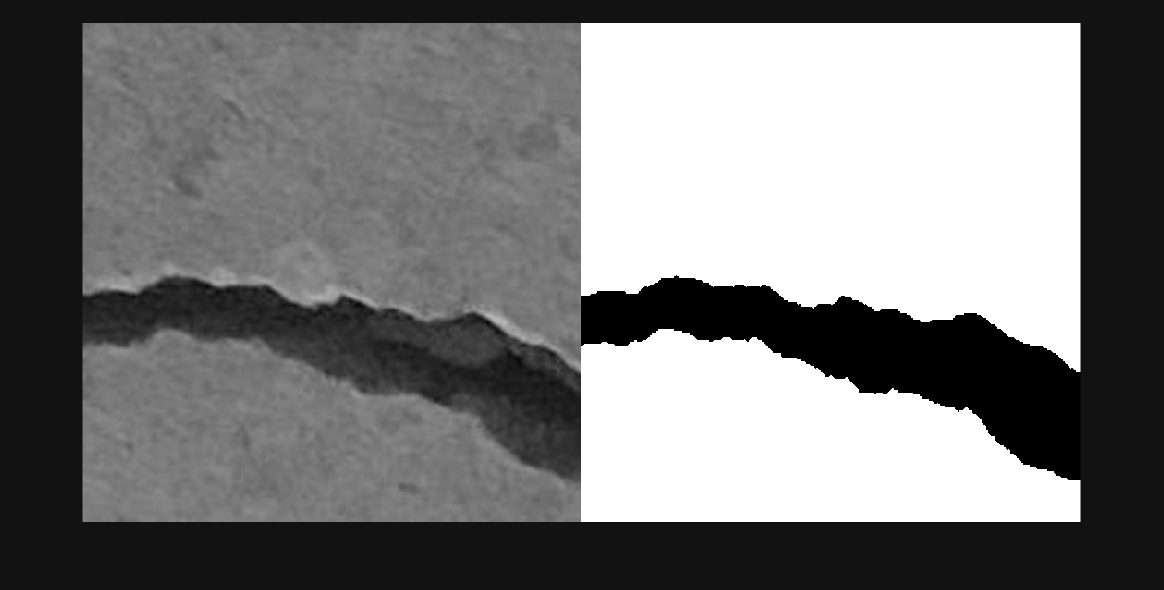

img187 = im2gray(imread("00187.jpg"));
BW1 = imbinarize(img187);
montage({img187,BW1})

However, if the object you want to segment is small or is only slightly different in intensity from the background, Otsu's method may choose a threshold value that doesn't isolate the intended region. For instance, image `00051.jpg`.

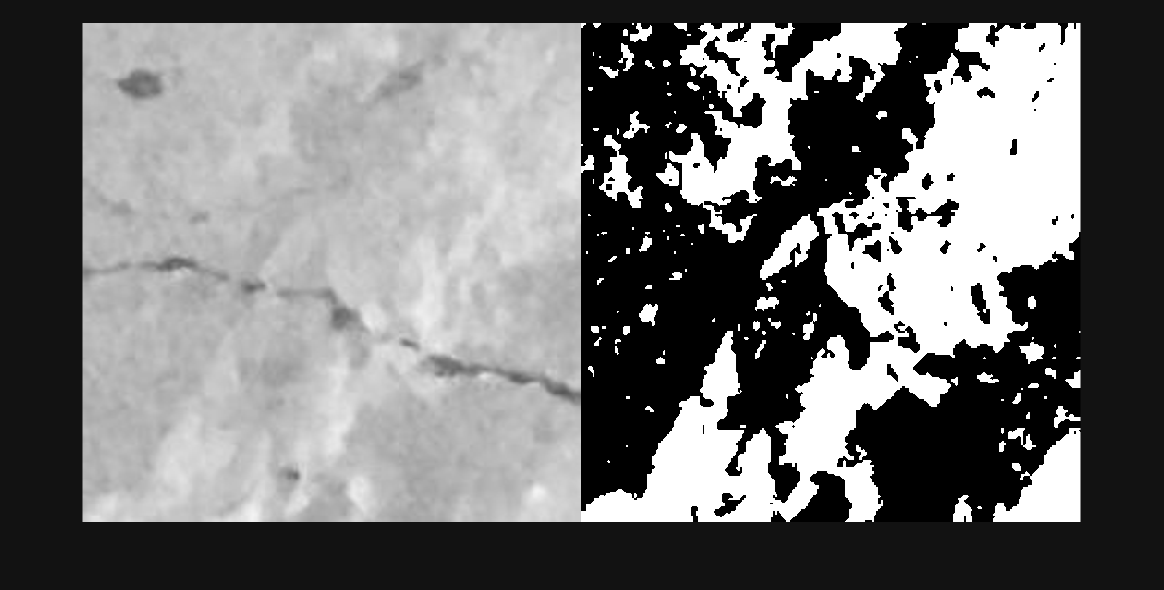

img051 = im2gray(imread("00051.jpg"));
BW2 = imbinarize(img051);
montage({img051,BW2})

## Effectiveness metric

You've seen that the graythresh function returns the theshhold value, but it can also return a second output called the* Effectiveness Metric*. This measures how well the threshold found by Otsu's method was able to segment the pixels into the two groups of *foreground *(white pixels in the masks above, represented by the logical `true`) and background (black pixels in the above masks, represented by the logical `false`).

An effectiveness metric with the minimum value of 0 means that the entire image had a single intensity, and no division was possible. An effectiveness metric with the maximum value of 1 means that pixels had only two possible intensity values, and a perfect division was possible.

Depending on your application, you can use this metric to judge how well Otsu's method could segment your image. For instance, below is the effectiveness metric for the previous two images:

[~,effectivenessMetric1] = graythresh(img187)

effectivenessMetric1 = 0.9010

[~,effectivenessMetric2] = graythresh(img051)

effectivenessMetric2 = 0.5379

### What the effectiveness metric measures

Note that this metric is NOT a measure of how well Otsu's method could segment the object you intended to isolate; it is only a measure of how well the pixels are divided into two groups based on their intensities, regardless of where those pixels are. Dividing pixels into two regions is only helpful you if your object only belongs to one of them. 

For instance, Otsu's method does an okay job isolating the crack in image `00167.jpg`, but the effectiveness value is still relatively low because the pixels are distributed across a range of intensities.

img167 = im2gray(imread("00167.jpg"));
BW3 = imbinarize(img167);
[~,effectivenessMetric3] = graythresh(img167)

effectivenessMetric3 = 0.6134

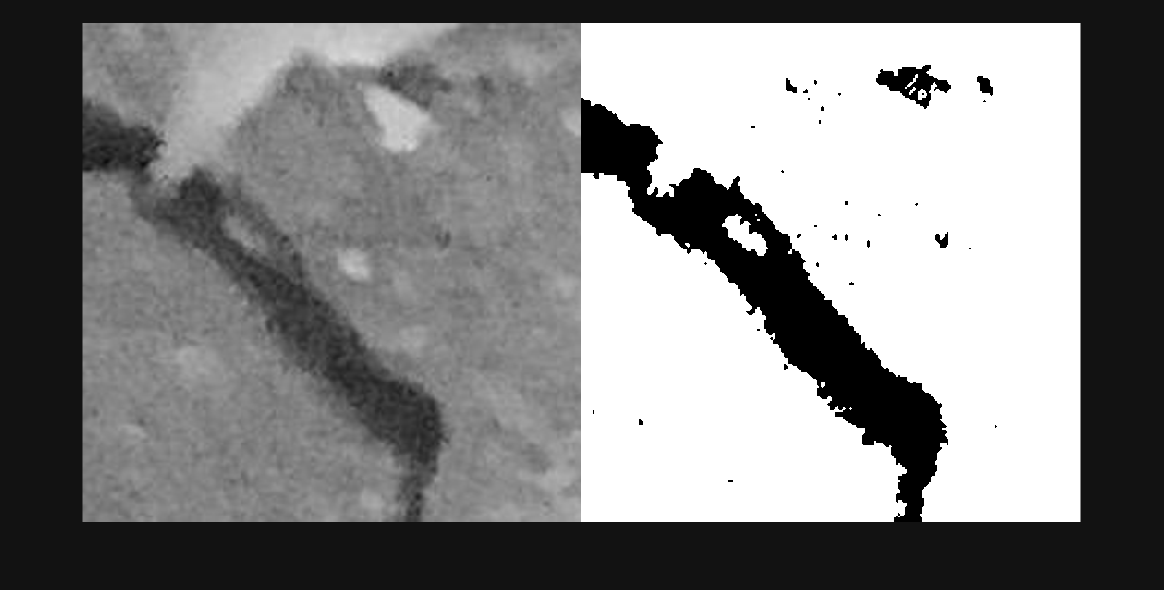

montage({img167,BW3})

## Setting a manual threshold

You can set your own threshold value manually using the second input to the `imbinarize` function. Here we've added a slider control for easy testing. Use this section to experiment with different images and values.

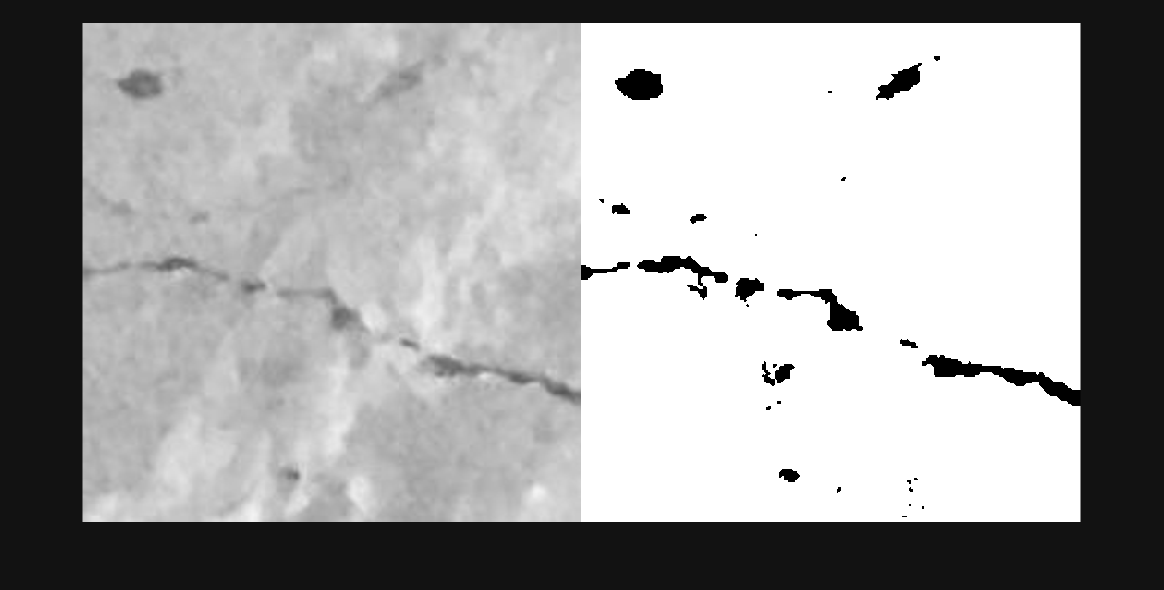

img = im2gray(imread("00051.jpg"));
BW = imbinarize(img,0.638);
montage({img,BW})

Don't worry if you can't achieve a "perfect" mask even with a manual threshold value. Later, you’ll learn techniques to adjust an initial binarization result to better match the object.

## Adaptive binarization

Use *adaptive binarization* in cases where your image has uneven illumination that causes the objects you want to segment to have different intensities depending on their location. Use the image of rice below to segment all of the light grains from the dark background.

There are two additional input options available to adaptive binarization:

- *Foreground Polarity*: Options are `Bright` (default) or `Dark`. Set to "bright" if your object is brighter than the background, and "dark" if it is darker than the background.

- *Sensitivity*: A value from `0` to `1`, with a default of `0.5`. A high sensitivity value leads to thresholding more pixels as foreground, at the risk of including some background pixels.

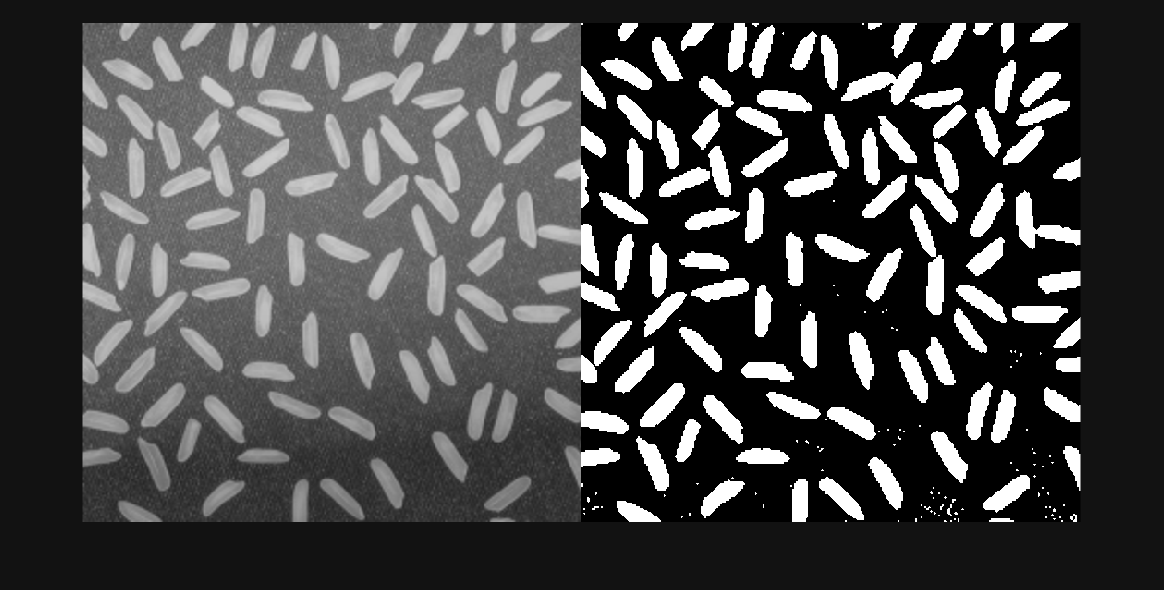

img = imread("rice.png");
BW = imbinarize(img,"adaptive",...
    "ForegroundPolarity","bright",...
    "Sensitivity",0.471);
montage({img,BW})

## Multilevel thresholding

Some applications require isolating multiple regions in the same image. Therefore, instead of a binary mask (with just true or false values), you can label each pixel with an integer and have as many values as needed. Use the slider in the code below to adjust the number of thresholds you would like to make. The number of resulting labels will be this number plus one. By default, `multithresh` also uses Otsu's method to find the threshold values.

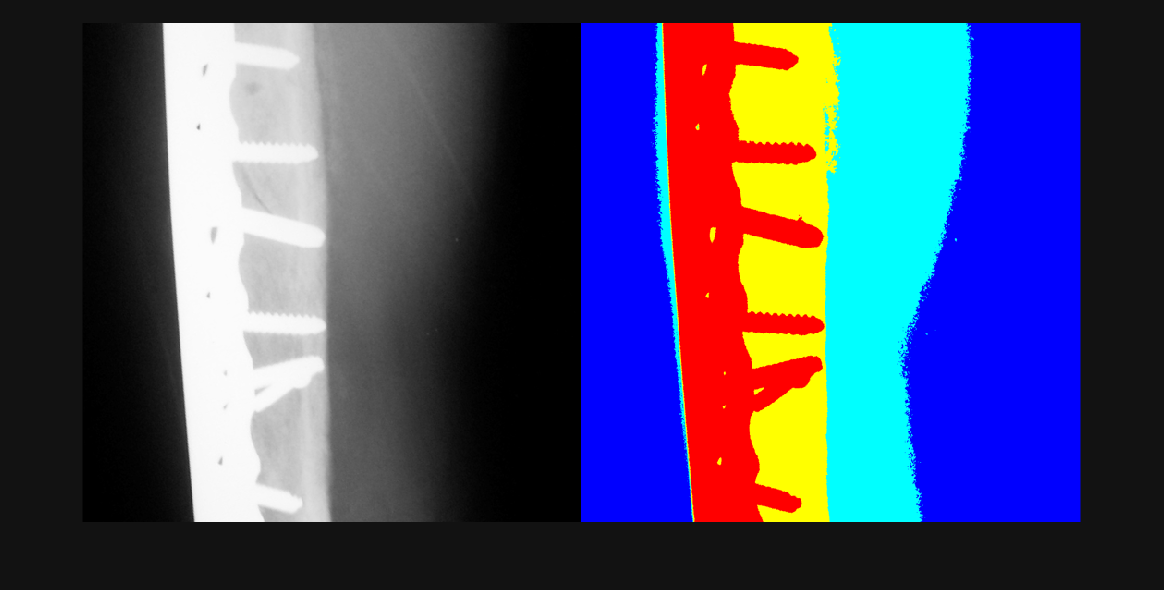

img = imread("armxray.png");
threshValues = multithresh(img,3);
labels = imquantize(img,threshValues);
labelsColor = label2rgb(labels);
montage({img,labelsColor})

## Setting a manual multilevel threshold

Just like with binarization, you can use your own values for multilevel thresholding. Play with the slider controls below to see if you can find better threshold values than Otsu's method for segmenting the four regions of: metal, bone, tissue, and background. Use the Image Viewer App to explore possible intensity values.

img = imread("armxray.png");
threshValues = [54,...
                169,...
                238];
threshValues

threshValues =     54   169   238


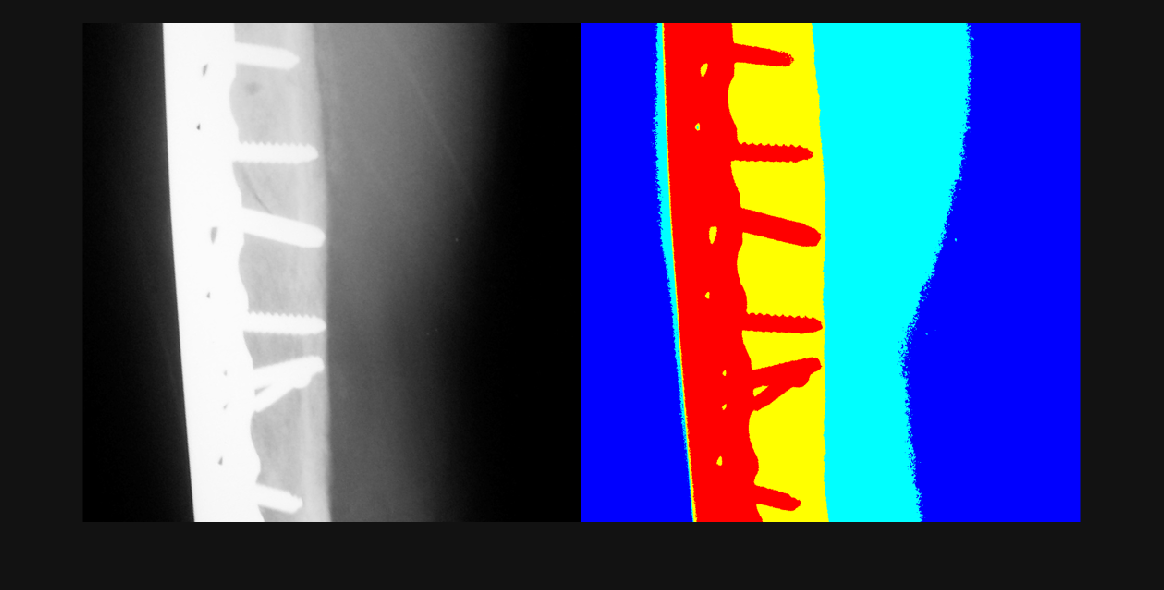

labels = imquantize(img,threshValues);
labelsColor = label2rgb(labels);
montage({img,labelsColor})

Try the above methods using your own images. We encourage you to share your results on the forums.

*Copyright 2022 The MathWorks, Inc.*